% Clear all variables in workspace
clear all

% Close all figures
close all

% Read in the "bus.jpeg" and "simpsons.jpeg" images
BUS=imread("bus.jpeg");
S=imread("simpsons.jpeg");

% Define a width of 20 pixels
width=20;

% Create a copy of the BUS image
B_4points=BUS;

% Define the four corner points of the bus image TR,TL,BR & BL
points=[[209,584];[230,801];[520,595];[468,808]];

### Top right corner

k=1;
for i=points(k,1)-width:points(k,1)
    for j=points(k,2)-width:points(k,2)
        % Set pixel values to 0 for the green and blue channels, and 255
        % the red one
        B_4points(i,j,1)=255;
        B_4points(i,j,2)=0;
        B_4points(i,j,3)=0;
    end
end

### Top left corner

k=2;
for i=points(k,1)-width:points(k,1)
    for j=points(k,2):points(k,2)+width
        % Set pixel values to 0 for the green and blue channels, and 255
        % the red one
        B_4points(i,j,1)=255;
        B_4points(i,j,2)=0;
        B_4points(i,j,3)=0;
    end
end

### Bottom right corner

k=3;
for i=points(k,1):points(k,1)+width
    for j=points(k,2)-width:points(k,2)
        % Set pixel values to 0 for the green and blue channels, and 255
        % the red one
        B_4points(i,j,1)=255;
        B_4points(i,j,2)=0;
        B_4points(i,j,3)=0;
    end
end

### Bottom left corner

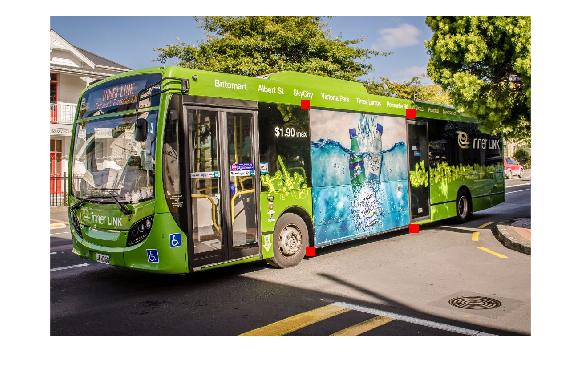

k=4;
for i=points(k,1):points(k,1)+width
    for j=points(k,2):points(k,2)+width
        % Set pixel values to 0 for the green and blue channels, and 255
        % the red one
        B_4points(i,j,1)=255;
        B_4points(i,j,2)=0;
        B_4points(i,j,3)=0;
    end
end

% Display the modified BUS image with the four corners
imshow(B_4points)

## Homography

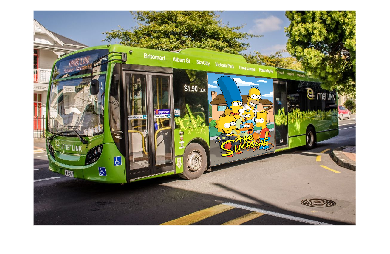

% Create a copy of the BUS image
SIMPSONS_BUS=BUS;

% Initialize a matrix of zeros with the same dimensions as the BUS image
I=zeros(size(BUS,1),size(BUS,2),size(BUS,3));

% Define the eight corresponding points in the two images
B=[points(5),points(1),points(6),points(2),points(7),points(3),points(8),points(4)]';

% Initialize a matrix for the transformation
T=zeros(8,8);

% Define the corners of the SIMPSONS image
[Y,X,Z]=size(S);
C=[0,0,X,0,0,Y,X,Y]';

% Create the transformation matrix
for i=1:4
    T(2*i-1,:)=[C(2*i),C(2*i-1),1,0,0,0,-C(2*i)*B(2*i-1),-C(2*i-1)*B(2*i-1)];
    T(2*i,:)=[0,0,0,C(2*i),C(2*i-1),1,-C(2*i)*B(2*i),-C(2*i-1)*B(2*i)];
end

% Solve for the coefficients of the transformation matrix
A=(T'*B)'/(T'*T);

% Construct the homography matrix
M=[A(1:3);A(4:6);A(7:8),1];

% Creation of the modified image
for i=1:Y
    for j=1:X
        a = M*[i,j,1]';
        SIMPSONS_BUS(round(a(2)/a(3)),round(a(1)/a(3)),:)=S(i,j,:);

    end    
end

%Display
imshow(SIMPSONS_BUS)

## Opposite Homography

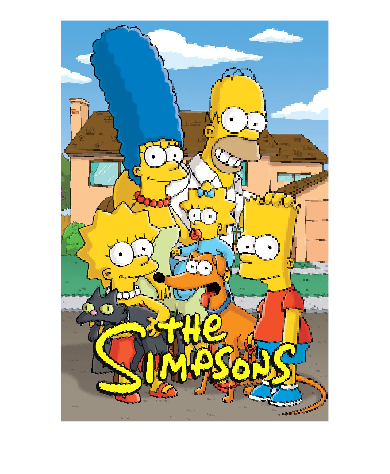

% Create a copy of the BUS image
SIMPSONS_2=zeros(1500,1000,3,'uint8');

% Define the four corner points of the bus image TR,TL,BR & BL
points=[[209,584];[230,801];[520,595];[379, 878]];

% Define the eight corresponding points in the two images
C_2=[points(5),points(1),points(6),points(2),points(7),points(3),points(8),points(4)]';

% Initialize a matrix for the transformation
T_2=zeros(8,8);

% Define the corners of the SIMPSONS image
[Y,X,Z]=size(S);
B_2=[0,0,0,X,Y,0,X,Y]';

% Create the transformation matrix
for i=1:4
    T_2(2*i-1,:)=[C_2(2*i),C_2(2*i-1),1,0,0,0,-C_2(2*i)*B_2(2*i-1),-C_2(2*i-1)*B_2(2*i-1)];
    T_2(2*i,:)=[0,0,0,C_2(2*i),C_2(2*i-1),1,-C_2(2*i)*B_2(2*i),-C_2(2*i-1)*B_2(2*i)];
end

% Solve for the coefficients of the transformation matrix
A_2=(T_2'*B_2)'/(T_2'*T_2);

% Construct the homography matrix
M_2=[A_2(1:3);A_2(4:6);A_2(7:8),1];
invM_2=inv(M_2);
normalized_invM_2=invM_2/invM_2(3,3);

% Creation of the modified image
for i=1:Y
    for j=1:X
        a = invM_2*[i,j,1]';
        %SIMPSONS_BUS_2(i,j,:)=S(round(a(2)/a(3)),round(a(1)/a(3)),:);
        SIMPSONS_2(i,j,:)=SIMPSONS_BUS(round(a(1)/a(3)),round(a(2)/a(3)),:);

    end    
end

%Display
imshow(SIMPSONS_2)

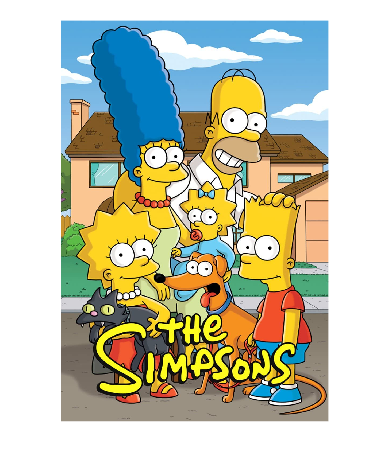


imshow(S)

## Images Comparison

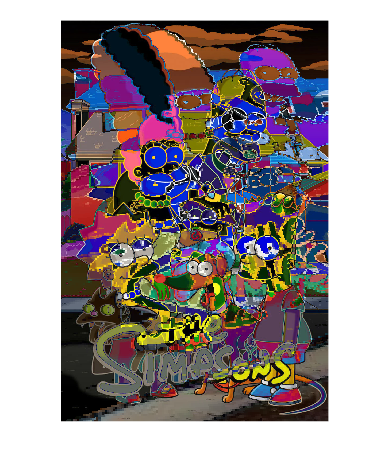

ssd_metric = sum(sum(sum((double(S)-double(SIMPSONS_2)).^2)));
Error_image=imshow(uint8(abs(int16(S) - int16(SIMPSONS_2))));

nb_blackpx_s=0;
nb_blackpx_s2=0;
for i=1:Y
    for j=1:X
        if S(i,j,:)==[255,255,255]
            nb_blackpx_s=nb_blackpx_s+1;
        end

        if SIMPSONS_2(i,j,:)==[255,255,255]
            nb_blackpx_s2=nb_blackpx_s2+1;
        
        end
    end
end
imshow(Error_image)

Error using imageDisplayValidateParams
Expected input number 1, I, to be one of these types:

double, single, uint8, uint16, uint32, uint64, int8, int16, int32, int64, logical

Instead its type was matlab.graphics.primitive.Image.

Error in images.internal.imageDisplayValidateParams (line 11)
validateattributes(common_args.CData, {'numeric','logical'},...

Error in 